# dual_axes

Adds a second axis with a linear conversion to other set of units to plot

## Syntax:

## Description: 

Adds a unit converted second axis to either y or x, or both. The second converted axis is placed opposed or on the same side as the main one. Axes are linked and can be panned and returned to home. *Opposed: the main x-axis is at the bottom and the added generated one by this funcion will be at the top of the plotting area; the second y-axis will be added to the right. *Same: the generated axis will be placed offset from the main one to the left (if y) or below (if x).

Notes: 

- Title must be fed and called by the function. If no title is desired, feed a blank ([]) or empty string ('') 

- All other modifiers need to be called BEFORE this function

## Inputs: 

- Axis:              Axis handler where to insert dual_axes 

- Title:              Figure title. DO NOT CALL TITLE OUTSIDE OF THIS! 

- Type:             'x','y', or 'xy' for opposed to main axes; 'xs','ys', or 'xys' for same side as main axes.

- Conversion:   Conversion factor from unit on plot to the one you want 

- Name:            New unit label 

- [conv2]:          Y-axis conversion factor when 'xy' or 'xys' is selected 

- [name2]:        Y-axis label when 'xy' or 'xys' is selected

## Outputs: 

- N/A

## Usage: 

You must call this function AFTER all figure modifiers (i.e: legends, limits, labels, etc.) EXCEPT title. This function calls the title, if no title is desired, enter a blank (i.e.: [] or ''s) 

- 'x' OR 'xs': X-axis

-  'y' OR 'ys': Y-axis 

-  'xy' OR 'xys': Both Axes 

## Examples: 

You can copy this code and paste it into the command window or select it and hit F9 on your keyboard: 

### Both axes, opposed 

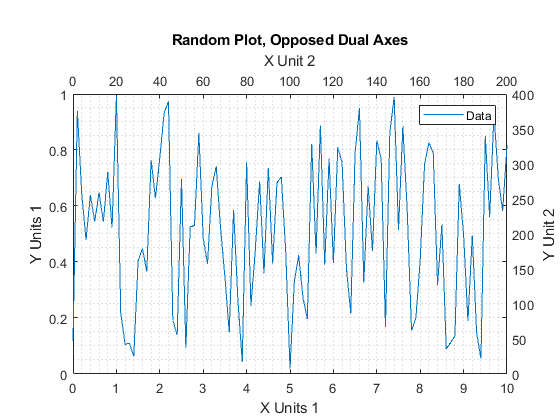

figure; 
x=0:0.1:10; 
y=rand(size(x)); 
plot(x,y,'-'); 
grid minor 
legend('Data'); 
xlabel('X Units 1'); 
ylabel('Y Units 1'); 
dual_axes(gca,'Random Plot, Opposed Dual Axes',... 
    'xy',20,'X Unit 2',400,'Y Unit 2');

### Both axes, same 

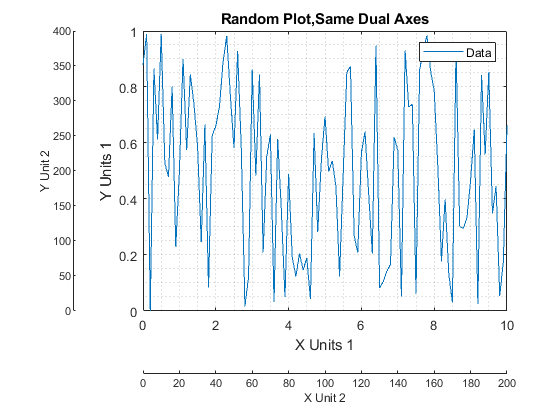

figure; 
x=0:0.1:10; 
y=rand(size(x)); 
plot(x,y,'-'); 
grid minor 
legend('Data'); 
xlabel('X Units 1'); 
ylabel('Y Units 1'); 
dual_axes(gca,'Random Plot,Same Dual Axes',... 
    'xys',20,'X Unit 2',400,'Y Unit 2');

### X-axis, opposed 

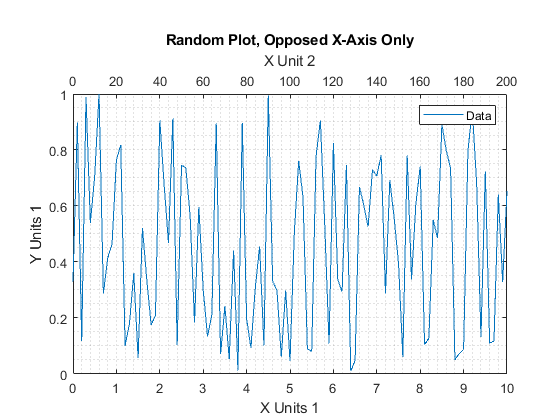

figure; 
x=0:0.1:10; 
y=rand(size(x)); 
plot(x,y,'-'); 
grid minor 
legend('Data'); 
xlabel('X Units 1'); 
ylabel('Y Units 1'); 
dual_axes(gca,'Random Plot, Opposed X-Axis Only',... 
    'x',20,'X Unit 2');

### X-axis, same 

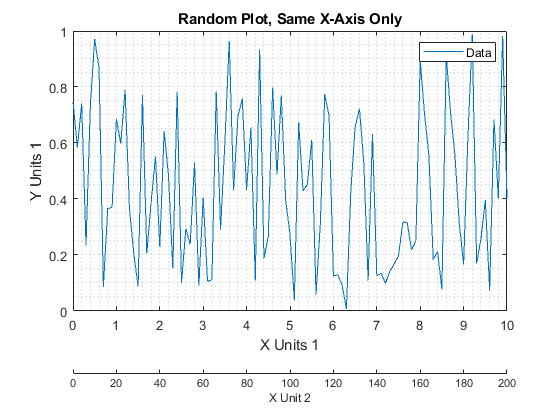

figure; 
x=0:0.1:10; 
y=rand(size(x)); 
plot(x,y,'-'); 
grid minor 
legend('Data'); 
xlabel('X Units 1'); 
ylabel('Y Units 1'); 
dual_axes(gca,'Random Plot, Same X-Axis Only',... 
    'xs',20,'X Unit 2');

### Y-axis, opposed 

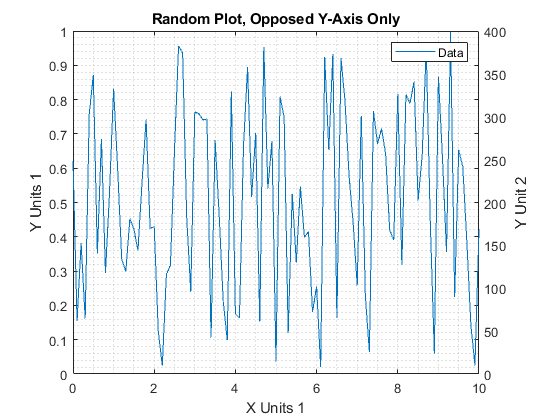

figure; 
x=0:0.1:10; 
y=rand(size(x)); 
plot(x,y,'-'); 
grid minor 
legend('Data'); 
xlabel('X Units 1'); 
ylabel('Y Units 1'); 
dual_axes(gca,'Random Plot, Opposed Y-Axis Only',... 
    'y',400,'Y Unit 2');

### Y-axis, same 

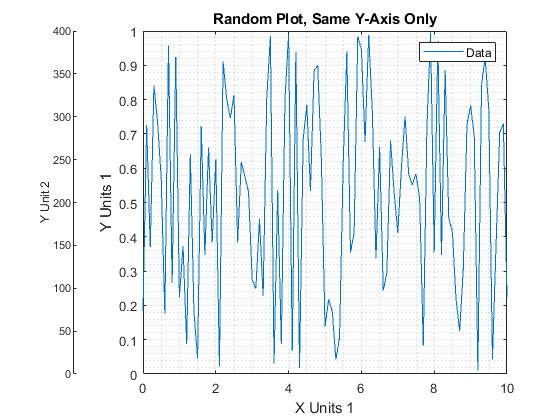

figure; 
x=0:0.1:10; 
y=rand(size(x)); 
plot(x,y,'-'); 
grid minor 
legend('Data'); 
xlabel('X Units 1'); 
ylabel('Y Units 1'); 
dual_axes(gca,'Random Plot, Same Y-Axis Only',... 
    'ys',400,'Y Unit 2');

-------------------------------------------------------------------------------------- 

Author: XSantacruz ([santacrx@gmail.com](mailto:santacrx@gmail.com)) 

Revison: 3.1 - 20220222 

--------------------------------------------------------------------------------------